# Chapter 1 Exercises

## Exercise 1.1

function [t, y] = euler(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
m = length(y0);
t = zeros(1, nsteps + 1);
y = zeros(nsteps + 1, m);

t(1) = tspan(1);
y(1,:) = y0;

for n = 1 : length(t) - 1
    y(n+1,:) = y(n,:) + h * f(t(n), y(n,:));
    t(n+1) = t(n) + h;
end

end

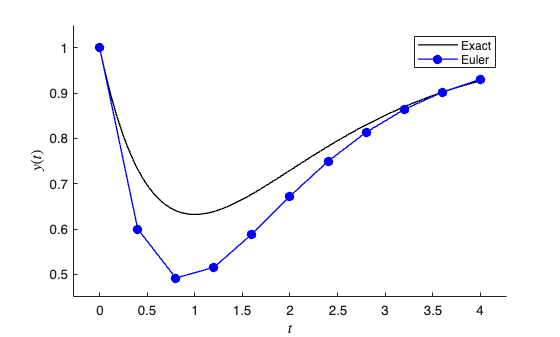

% Define ODE function
f = @(t, y) 1 - exp(-t) - y;

% Define IVP parameters
tspan = [0, 4];    % boundaries of the t domain
y0 = 1;          % initial values
h = 0.4;           % step length

% Solve the IVP using the Euler method
[t, y] = euler(f, tspan, y0, h);

% Define exact solution
exact = @(t, y) 1 - t .* exp(-t);

% Calculate exact solution over lots of values of t
texact = linspace(0, 4, 100);
yexact = exact(texact);

% Plot solution
clf
hold on
plot(texact, yexact, 'k-', LineWidth=1)
plot(t, y(:,1), 'b-o', LineWidth=1, MarkerFaceColor='b')
hold off
xlabel('$t$', Interpreter='latex')
ylabel('$y(t)$', Interpreter='latex')
legend('Exact', 'Euler')
axis padded

(b)

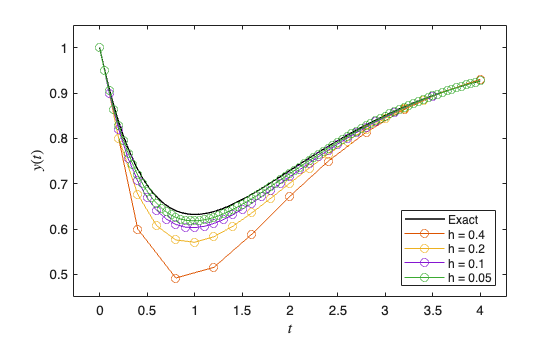

% Plot exact solution
clf
h(1) = plot(texact, yexact, 'k-', LineWidth=1);
hold on

% Loop through h values and plot solution
hvals = [0.4, 0.2, 0.1, 0.05];
for i = 1 : length(hvals)
    [t, y] = euler(f, tspan, y0, hvals(i));
    h(i+1) = plot(t, y(:, 1), '-o');
end

hold off
xlabel('$t$', Interpreter='latex')
ylabel('$y(t)$', Interpreter='latex')
legend(h, {'Exact', 'h = 0.4', 'h = 0.2', 'h = 0.1', 'h = 0.05'}, Location="southeast")
axis padded

(c)

if true % used to keep printed lines together

    errors = [];    % empty list for the errors

    % Print column headings
    fprintf("|  h   |  Euler   |   GTE    |")
    fprintf("|:----:|:--------:|:--------:|")

    % Loop through solutions
    for i = 1 : length(hvals)
        [t, y] = euler(f, tspan, y0, hvals(i));
        [~, idx] = min(abs(t - 2));
        errors = [errors, abs(y(idx,1) - exact(t(idx)))];
        fprintf("| %0.2f | %0.6f | %0.2e |\n", hvals(i), y(idx,1), errors(i))
    end
end

|  h   |  Euler   |   GTE    |

|:----:|:--------:|:--------:|

| 0.40 | 0.672496 | 5.68e-02 |
| 0.20 | 0.701442 | 2.79e-02 |
| 0.10 | 0.715579 | 1.38e-02 |
| 0.05 | 0.722507 | 6.82e-03 |


(d)

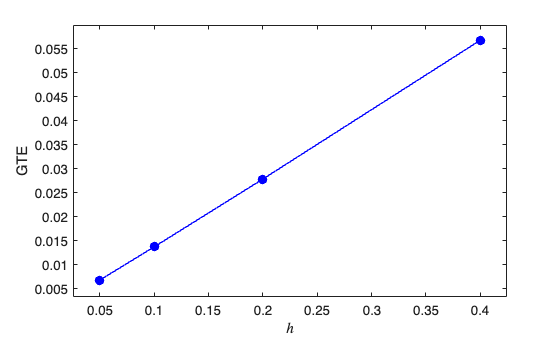

clf
plot(hvals, errors, 'b-o', LineWidth=1, MarkerFaceColor='b')
xlabel("$h$", Interpreter="latex")
ylabel("GTE")
axis padded

## Exercise 1.2

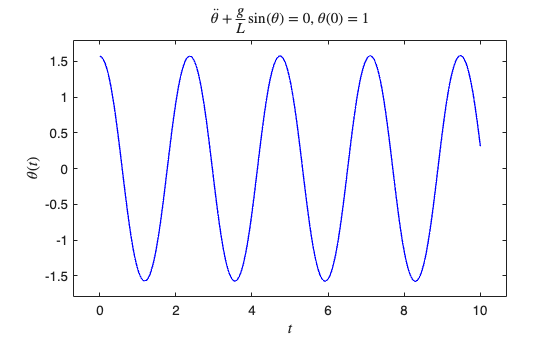

% Define ODE function
pendulum = @(t, y, L, g) [ y(2), -g / L * sin(y(1)) ];

% Define IVP parameters
tspan = [0, 10];    % boundaries of the t domain
y0 = [pi / 2, 0];   % initial values
L = 1;              % length of pendulum
g = 9.81;           % gravity
h = 0.0001;         % step length

% Solve the IVP using the Euler method
[t, y] = euler(@(t, y)pendulum(t, y, L, g), tspan, y0, h);

% Plot solution
clf
plot(t, y(:,1), 'b-', LineWidth=1)
xlabel('$t$', Interpreter='latex')
ylabel('$\theta(t)$', Interpreter='latex')
title('$\ddot{\theta} + \frac{g}{L}\sin(\theta)=0$, $\theta(0) = 1$', Interpreter='latex')
axis padded

## Exercise 1.3

(a)

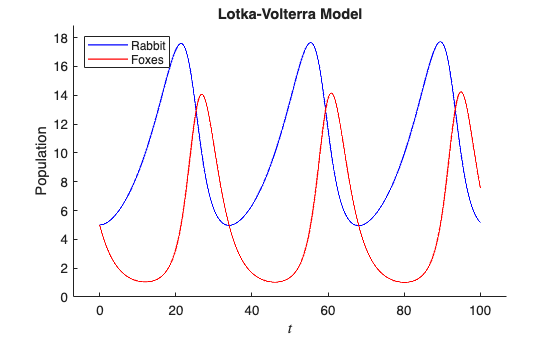

% Define ODE function
predator_prey = @(t, y, a, b, c, d) [ a * y(1) - b * y(1) * y(2), -c * y(2) + d * y(1) * y(2) ];

% Define IVP parameters
tspan = [0, 100];   % boundaries of the t domain
y0 = [5, 5];        % initial values
a = 0.1;            % rabbit birth rate
b = 0.02;           % rabbit death rate
c = 0.4;            % fox birth rate
d = 0.04;           % fox death rate
h = 0.01;           % step length

% Solve the IVP using the Euler method
[t, y] = euler(@(t, y)predator_prey(t, y, a, b, c, d), tspan, y0, h);

% Plot solution
clf
hold on
plot(t, y(:,1), 'b-', LineWidth=1)
plot(t, y(:,2), 'r-', LineWidth=1)
hold off
xlabel('$t$', Interpreter='latex')
ylabel('Population')
title('Lotka-Volterra Model')
legend('Rabbit', 'Foxes', Location='northwest')
axis padded

(b)

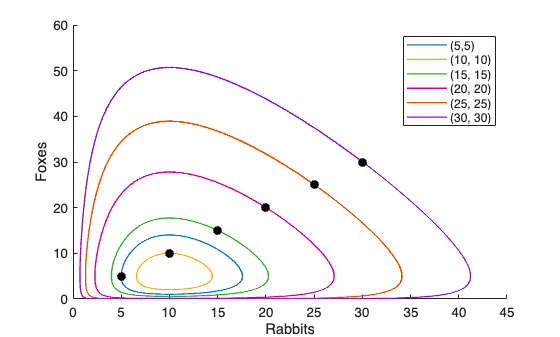

% Use smaller step length to increase accuracy
h = 0.001;

clf
hold on
for i = 1 : 6
    [t, y] = euler(@(t, y)predator_prey(t, y, a, b, c, d), tspan, y0, h);
    hi(i) = plot(y(:,1), y(:,2), LineWidth=1);
    plot(y0(1), y0(2), 'ko', MarkerFaceColor='k')
    y0 = y0 + [5, 5];
end
hold off
xlabel("Rabbits")
ylabel("Foxes")
legend(hi, {'(5,5)', '(10, 10)', '(15, 15)', '(20, 20)', '(25, 25)', '(30, 30)'})